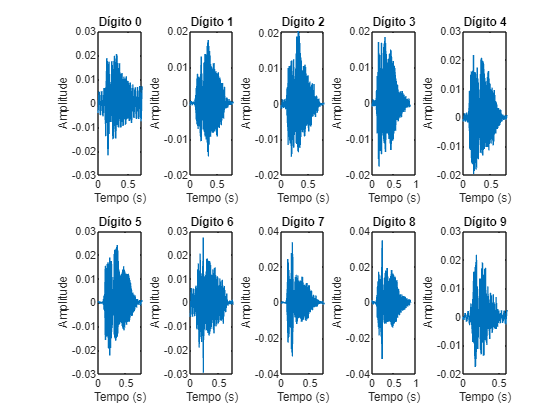

filePath = 'C:\Users\User\Desktop\uni\ATD\Projeto1\55\';
audioFiles = [];
y = cell(1, length(audioFiles));
%Importar os audio usando a função audioread
for i = 0 : 9
    for j = 0 : 49
        file = i + "_55_" + j + ".wav";
        audioFiles = [audioFiles, file];
    end
end
for i = 1:length(audioFiles)
    file = append(filePath, audioFiles{i});
    [y{i}, Fs] = audioread(file);
end

grafico(y, Fs);


%Adicionar silencio no inicio
limite = 5e-3; %Limite que consideramos silenico ou seja sempre que o intervalo tem a amplitude maxima menor que 0.005
for j = 1:length(y)
    duracaoJanela = 0.002; %Tamanho da janela de pesquisa
    comprimentoJanela = duracaoJanela * Fs;
    comrimentoTotal = length(y{j});
    numeroJanelas = floor(comrimentoTotal / comprimentoJanela);
    yNovo = [];
    for i = 1 : numeroJanelas
        yJanela = y{j}((i-1)*comprimentoJanela+1:comprimentoJanela*i);
        if max(yJanela) > limite
            yNovo = y{j}((i-1)*comprimentoJanela+1:end);
            break;
        end
    end
    y{j} = yNovo;
end


%Adicionar ou remover o silencio no fim
duracaoMax = 0.6 %Duração do audio com mais tempo antes do silencio

duracaoMax = 0.6000

for i = 1:length(y)
    if(length(y{i}) < duracaoMax * Fs)
        y{i} = [y{i}; zeros(duracaoMax*Fs - length(y{i}), 1)];
    else
        y{i} = y{i}(1:duracaoMax*Fs);
    end
end


%Normalizar amplitude
amplitudeMax = max(abs(y{1}));
amplitudeMin = min(abs(y{1}));
for i = 2:length(y)
    amplitudeMaxAux = max(abs(y{i}));
    amplitudeMinAux = min(abs(y{i}));
    if amplitudeMaxAux > amplitudeMax
        amplitudeMax = amplitudeMaxAux;
    end
    if amplitudeMinAux < amplitudeMin
        amplitudeMin = amplitudeMinAux;
    end
end

valorMax = amplitudeMax / length(y);
valorMin = amplitudeMin / length(y);
for i = 1:length(y)
    y{i} = y{i} / valorMax;
end


num = {0, 1, 2, 3, 4, 5, 6, 7, 8, 9}

num = 1×10 cell array
    {[0]}    {[1]}    {[2]}    {[3]}    {[4]}    {[5]}    {[6]}    {[7]}    {[8]}    {[9]}


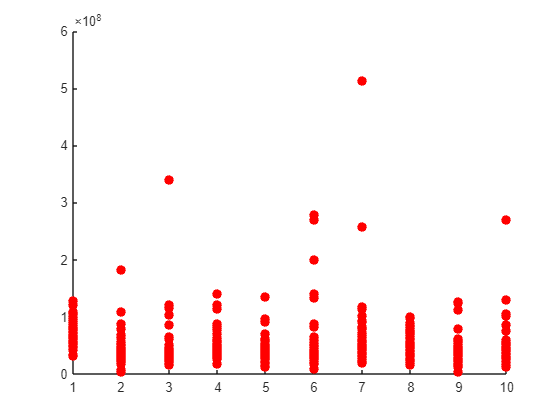

energia = 1.0e+08 *

    0.8684    0.4953    0.4842    0.6502    0.8133    0.8268    0.8926    0.7904    1.0906    0.4891    0.8096    0.4779    0.4360    1.0036    0.9046    0.9651    0.6696    0.4312    0.5686    0.6336    0.8988    0.5544    1.2930    0.7829    0.6876    0.8286    0.5901    0.6273    0.6363    0.8061    0.7910    0.7284    0.8276    0.5736    1.0613    0.7460    0.3496    1.2214    0.7742    0.5396    1.0704    0.6623    1.0901    0.9422    0.7706    0.6335    0.7697    0.4876    0.3192    0.6472



energia = energiaTotal(y)

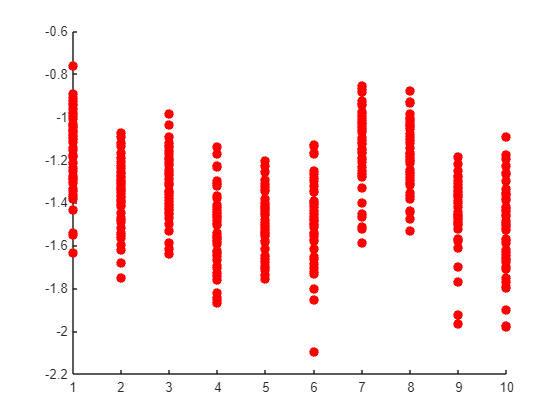

razaoAmp =    -0.9396   -1.1742   -1.3791   -1.0399   -1.1008   -1.0879   -0.9224   -1.1172   -1.1004   -1.2369   -0.9448   -1.0474   -1.0837   -1.2141   -1.0673   -0.9596   -1.1832   -1.5392   -1.2495   -1.0991   -0.9863   -1.2886   -1.3057   -1.3616   -1.2847   -1.0397   -1.2754   -1.5500   -0.9973   -1.3436   -1.1454   -1.6346   -0.7618   -1.3731   -0.8929   -1.1505   -1.1820   -1.0092   -0.9091   -1.0587   -1.0343   -1.4315   -1.0296   -1.0072   -1.0627   -1.2788   -1.3367   -1.2919   -1.0317   -0.9804



razaoAmp = razaoAmplitude(y)

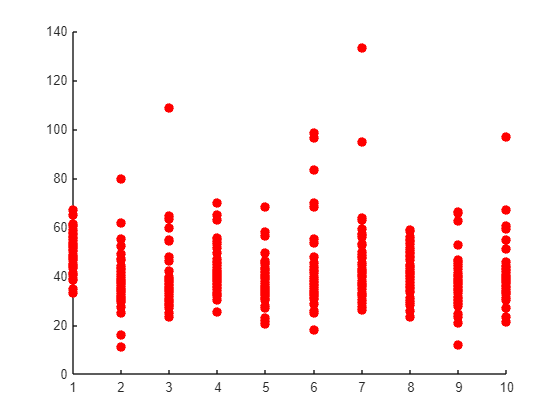

desvioP =    54.9077   41.4730   41.0017   47.5135   53.1425   53.5796   55.6695   52.3865   61.5377   41.2103   53.0197   40.7376   38.9106   59.0317   56.0421   57.8876   48.2186   38.6940   44.4332   46.9032   55.8644   43.8747   67.0047   52.1401   48.8611   53.6397   45.2664   46.6705   46.9995   52.9069   52.4088   50.2908   53.6081   44.6298   60.7060   50.8951   34.8418   65.1230   51.8498   43.2842   60.9662   47.9562   61.5233   57.1981   51.7287   46.8991   51.6986   41.1470   33.2894   47.4057



desvioP = desvioPadrao(y)


caracteristicas = [energia; razaoAmp; desvioP];
caracteristicas = caracteristicas';
figure;
scatter3(caracteristicas(:,1), caracteristicas(:,2), caracteristicas(:,3), 50, 'filled');xlabel('Energia Total');

Unrecognized function or variable 'boxplot3'.

xlabel('Energia Total');

ylabel('Razão de Amplitude');
zlabel('Desvio Padrão');


function grafico(y, Fs)
for i = 1:10
    subplot(2, 5, i)
    t = (0:length(y{i}) - 1) / Fs;
    plot(t, y{i});
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title(['Dígito ', num2str(i-1)]);
end
end


function energia = energiaTotal(y)
    figure;
    energia = zeros(1, length(y));
    for i = 1: 10
        for j = 1: 50
            energia(j+50*(i-1))  = sum(y{j+50*(i-1)}.^2);
            scatter(i, energia(j+50*(i-1)), 50,"red" ,"filled", "o");
            hold on;
        end
    end
end

function razaoAmplitude = razaoAmplitude(y)
    figure;
    razaoAmplitude = zeros(1, length(y));
    for i = 1 : 10
        for j = 1 : 50
        amplitudeMax = max(y{j+50*(i-1)});
        amplitudeMin = min(y{j+50*(i-1)});
        razaoAmplitude(j+50*(i-1)) = amplitudeMax/amplitudeMin;
        scatter(i, razaoAmplitude(j+50*(i-1)), 50,"red" ,"filled", "o");
        hold on
        end
    end
end

function desvioPadrao = desvioPadrao(y)
    figure;
    desvioPadrao = zeros(1, length(y));
    for i = 1 : 10
        for j = 1 : 50
            desvioPadrao(j+50*(i-1)) = std(y{j+50*(i-1)});
            scatter(i, desvioPadrao(j+50*(i-1)), 50,"red" ,"filled", "o");
            hold on
        end
    end
end